clc;
	clear;
	close all;
	
	load('datacircle.mat');
	
	% Build the least-squares problem
	z = x.^2 + y.^2;
	C = [2*x, 2*y, ones(length(x),1)];
	[n,p] = size(C);
	
	% Least-squares solution
	theta = C \ z;
	a = theta(1);
	b = theta(2);
	c = theta(3);
	R = sqrt(c + a^2 + b^2);
	
	% Linear model used for statistical analysis
	mdl = fitlm([2*x, 2*y], z);
	anova_table = anova(mdl,'summary');
	coef_table = mdl.Coefficients;
	
	% Fitted values and residuals
	z_hat = mdl.Fitted;
	e = mdl.Residuals.Raw;
	
	% Performance indicators
	SSE = sum(e.^2);
	MSE = SSE / n;
	s2 = SSE / (n - p);
	RMSE = sqrt(s2);
	SST = sum((z - mean(z)).^2);
	R2 = 1 - SSE / SST;
	adjR2 = 1 - (SSE/(n-p)) / (SST/(n-1));
	
	% Hat matrix and leverage
	H = C * ((C' * C) \ C');
	h = diag(H);
	
	% Standardized residuals and Cook's distances
	r = zeros(n,1);
	D = zeros(n,1);
	for i = 1:n
	r(i) = e(i) / sqrt(s2 * (1 - h(i)));
	D(i) = (e(i)^2 / (p * s2)) * (h(i) / (1 - h(i))^2);
	end
	
	% Summary table
	summary_table = table((1:n)', x, y, z, z_hat, e, h, r, D, ...
	'VariableNames', {'Obs','x','y','z','z_hat','Residual', ...
	'Leverage','StdResidual','CooksDistance'});
	
	% Sort the most atypical observations
	[~, idx_cook] = sort(D, 'descend');
	[~, idx_res] = sort(abs(r), 'descend');
	top_cook = summary_table(idx_cook(1:10), :);
	top_res = summary_table(idx_res(1:10), :);
	
	% Display results
	fprintf('a = %.6f\n', a);

a = -0.974401


	fprintf('b = %.6f\n', b);

b = 1.978400


	fprintf('R = %.6f\n', R);

R = 3.045140


	
	fprintf('SSE   = %.6f\n', SSE);

SSE   = 265.626539


	fprintf('MSE   = %.6f\n', MSE);

MSE   = 2.656265


	fprintf('s^2   = %.6f\n', s2);

s^2   = 2.738418


	fprintf('RMSE  = %.6f\n', RMSE);

RMSE  = 1.654817


	fprintf('R^2   = %.6f\n', R2);

R^2   = 0.971053


	fprintf('AdjR2 = %.6f\n', adjR2);

AdjR2 = 0.970456


	
	disp(coef_table);

                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________
    (Intercept)     4.4094      0.23915     18.437    1.8157e-33
    x1             -0.9744     0.038198    -25.509     8.308e-45
    x2              1.9784     0.038663      51.17    5.4084e-72


	disp(anova_table);

                SumSq     DF    MeanSq     F        pValue  
                ______    __    ______    ____    __________
    Total       9176.4    99    92.691                      
    Model       8910.7     2    4455.4    1627    2.4415e-75
    Residual    265.63    97    2.7384                      


	disp(summary_table(1:10,:));

    Obs      x         y         z       z_hat     Residual    Leverage    StdResidual    CooksDistance
    ___    ______    ______    ______    ______    ________    ________    ___________    _____________
     1     2.3169    2.3558    10.918    9.2155     1.7023     0.033313       1.0463         0.012574  
     2     1.6834    2.3611    8.4086    10.471    -2.0624     0.025296      -1.2623         0.013785  
     3     1.5996    2.4034    8.3348    10.802     -2.467     0.024427      -1.5094         0.019014  
     4     2.2668    2.3666    10.739    9.3559     1.3831     0.032631      0.84976        0.0081193  
     5     2.0417    2.9574    12.915    12.132    0.78272     0.03127

	disp(top_cook);

    Obs       x           y         z        z_hat      Residual    Leverage    StdResidual    CooksDistance
    ___    ________    _______    ______    ________    ________    ________    ___________    _____________
    39      -3.5922     4.3779     32.07      28.732     3.3376     0.037018       2.0553        0.054127   
    14      0.62018     3.7069    14.125      17.868    -3.7426     0.021639      -2.2865        0.038545   
    11       1.6762     4.2177    20.599      17.831     2.7676      0.03547        1.703        0.035549   
    12       1.6535     4.2438    20.744      17.979     2.7649     0.035466       1.7013        0.035475   
    77     -0.56015    -1.4459    2.4045

	disp(top_res);

    Obs       x           y           z        z_hat      Residual    Leverage    StdResidual    CooksDistance
    ___    ________    ________    _______    ________    ________    ________    ___________    _____________
    14      0.62018      3.7069     14.125      17.868    -3.7426     0.021639      -2.2865        0.038545   
    39      -3.5922      4.3779      32.07      28.732     3.3376     0.037018       2.0553        0.054127   
    56      -3.3899      1.4119     13.485      16.602    -3.1173     0.023185       -1.906        0.028743   
     6       1.3663      2.8177     9.8064      12.896    -3.0894     0.023051      -1.8888        0.028059   
    75      -0.6892    -0.54

	
	if max(abs(r)) < 2
	fprintf('No standardized residual exceeds |2|.\n');
	else
	fprintf('A few observations deserve attention in the residual analysis.\n');
	end

A few observations deserve attention in the residual analysis.


	
	if max(D) < 1
	fprintf('No observation appears strongly influential under the D_i > 1 rule.\n');
	else
	fprintf('At least one observation appears influential.\n');
	end

No observation appears strongly influential under the D_i > 1 rule.


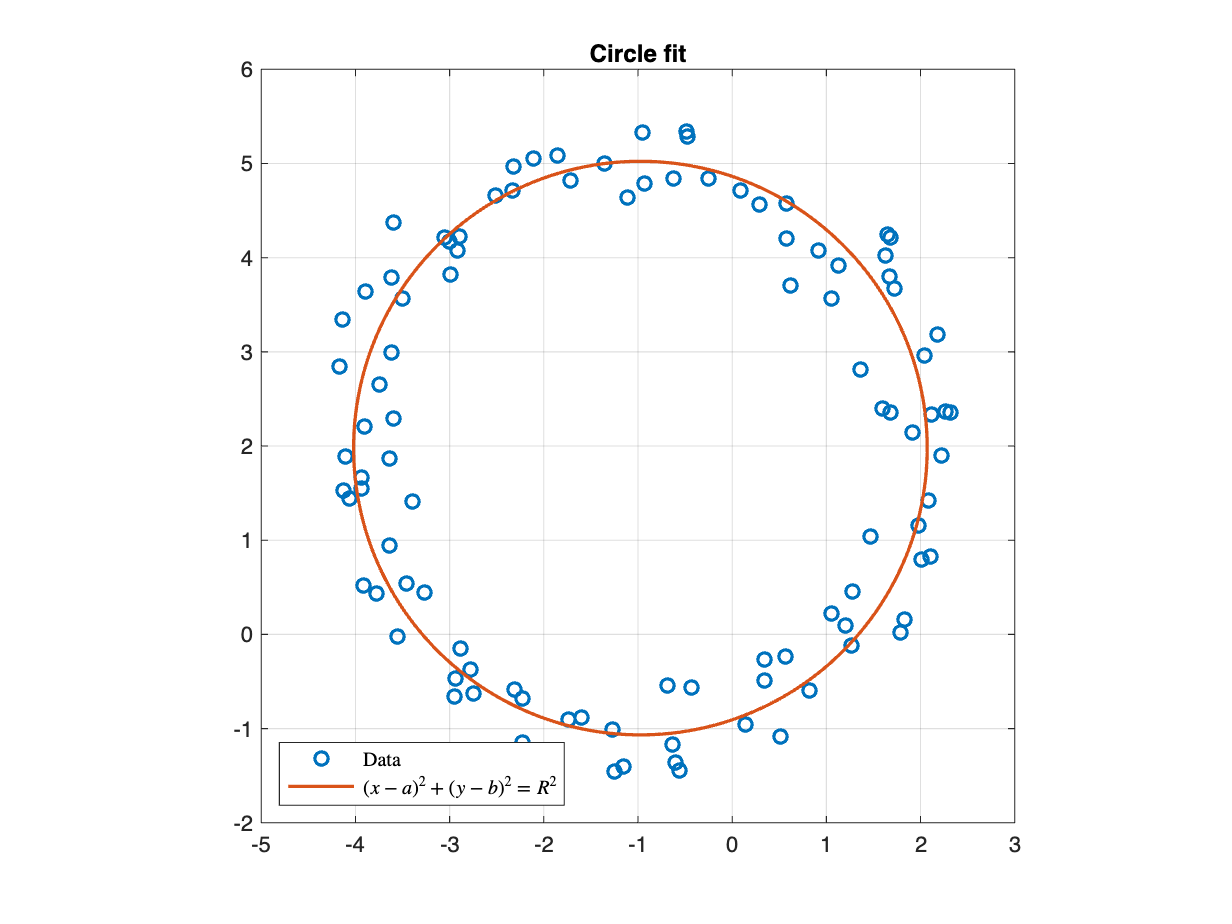

	
	% Plot fitted circle
	figure('Color','w');
	t = linspace(0,2*pi,400);
	plot(x,y,'o',a + R*cos(t),b + R*sin(t),'-','LineWidth',1.5)
	xlim([-5 3]);
	ylim([-2 6]);
	grid on;
	daspect([1 1 1]);
	legend({'Data','$(x-a)^2+(y-b)^2=R^2$'}, ...
	'Interpreter','latex','Location','southwest');
	title('Circle fit');
	saveas(gcf,'Figures/FigureCircle.pdf')
set(gcf,'Units','centimeters');
screenposition = get(gcf,'Position');
set(gcf,...
    'PaperPosition',[0 0 screenposition(3:4)],...
    'PaperSize',[screenposition(3:4)]);
print -dpdf -painters Figures/FigureCircle

cleanfigure;
matlab2tikz('Figures/FigureCircle.tex','width','\figwidth','height','\figheight','showInfo',false);

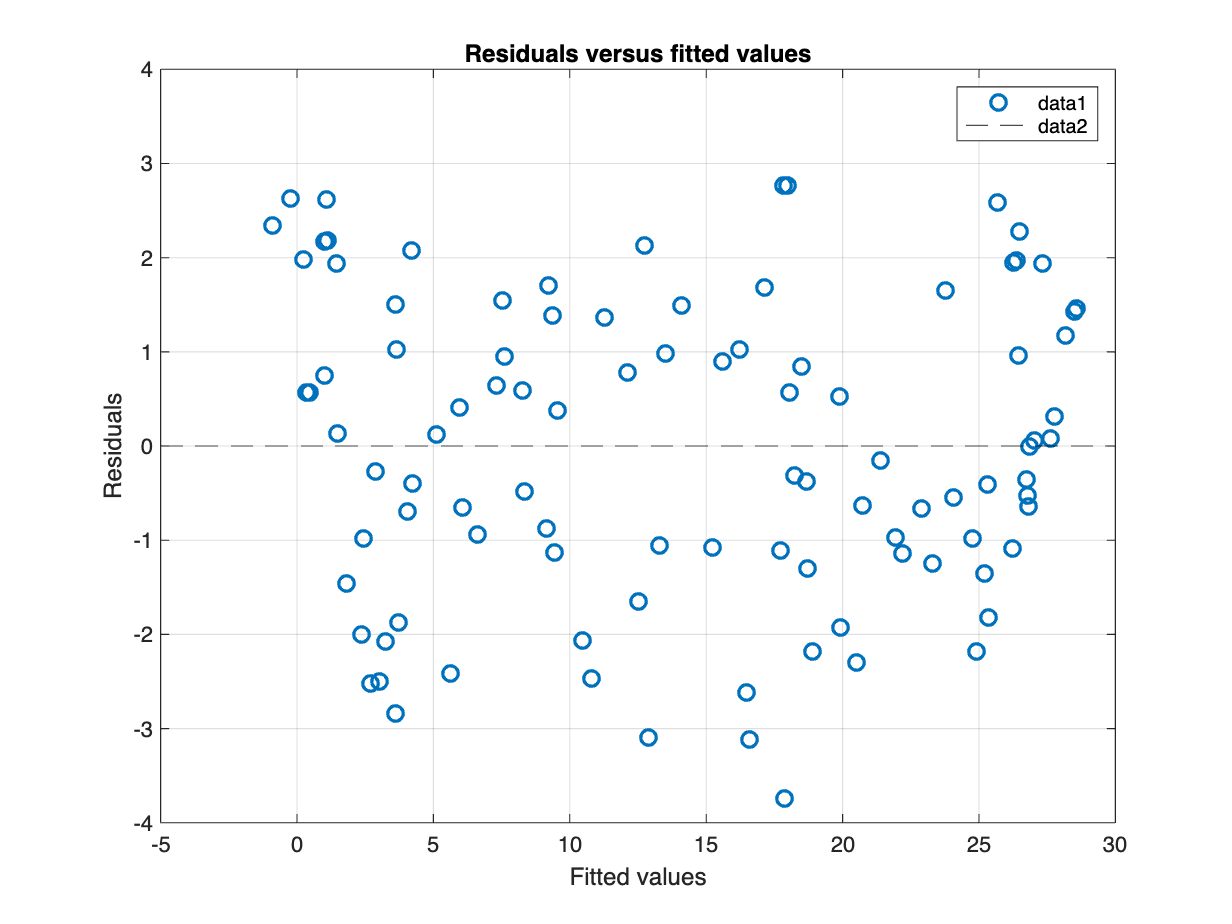

Error using matlab2tikz>handleAllChildren (line 730)
I don't know how to handle this object: constantline

Error in matlab2tikz>drawAxes (line 880)
    [m2t, childrenEnvs] = handleAllChildren(m2t, handle);
Error in 



	% Residual plot
	figure('Color','w');
	plot(z_hat,e,'o','LineWidth',1.5,'MarkerSize',7);
	grid on;
	xlabel('Fitted values');
	ylabel('Residuals');
	title('Residuals versus fitted values');
	yline(0,'--k');
saveas(gcf,'Figures/FigureCircleResidual.pdf')
set(gcf,'Units','centimeters');
screenposition = get(gcf,'Position');
set(gcf,...
    'PaperPosition',[0 0 screenposition(3:4)],...
    'PaperSize',[screenposition(3:4)]);
print -dpdf -painters Figures/FigureCircleResidual

cleanfigure;
matlab2tikz('Figures/FigureCircleResidual.tex','width','\figwidth','height','\figheight','showInfo',false);


saveas(gcf,'Figures/FigureCircle.pdf')
set(gcf,'Units','centimeters');
screenposition = get(gcf,'Position');
set(gcf,...
    'PaperPosition',[0 0 screenposition(3:4)],...
    'PaperSize',[screenposition(3:4)]);
print -dpdf -painters Figures/FigureCircle

%cleanfigure;
%matlab2tikz('Figures/FigureCircle.tex','width','\figwidth','height','\figheight','showInfo',false);